# Diagrama de Bode - abordagem prática

## Boas práticas

clear all;
clc;
close all;


## Definindo um sistema dinâmico


Gma = tf([1 1000],[1 20 100]);
[mag,phase,w] = bode(Gma,{0.01,1e5});
[Gm,Pm,Wcg,Wcp] = margin(Gma)

Gm = Inf

Pm = 38.5808

Wcg = NaN

Wcp = 30.0069


figure(1)
subplot(2,1,1)
semilogx(w, 20*log10(squeeze(mag)), '-b', 'LineWidth',2);
xline(Wcp,'r-.','LineWidth',2)
yline(0,'r-.','LineWidth',2)
grid
subplot(2,1,2)
semilogx(w, squeeze(phase), '-b', 'LineWidth',2)
hold;

Current plot held


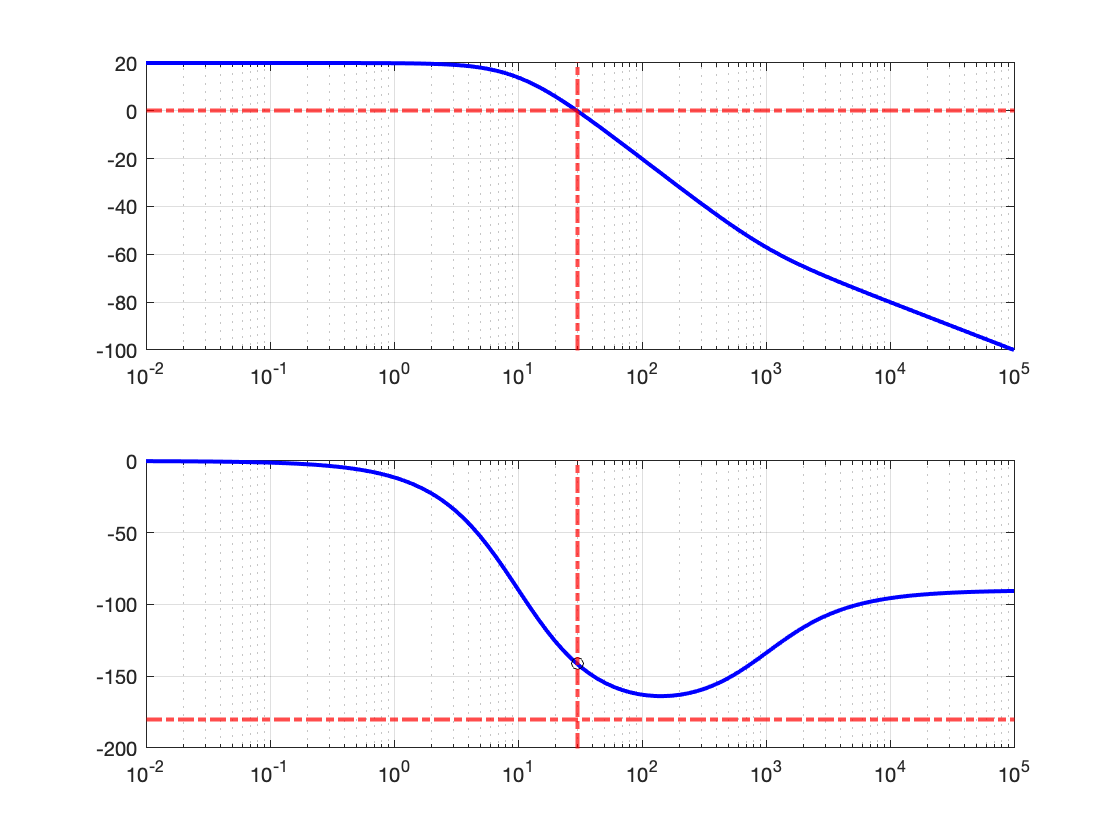

plot(Wcp,-180+Pm,'ko')
xline(Wcp,'r-.','LineWidth',2)
yline(-180,'r-.','LineWidth',2)
grid;

## Lugar das raízes

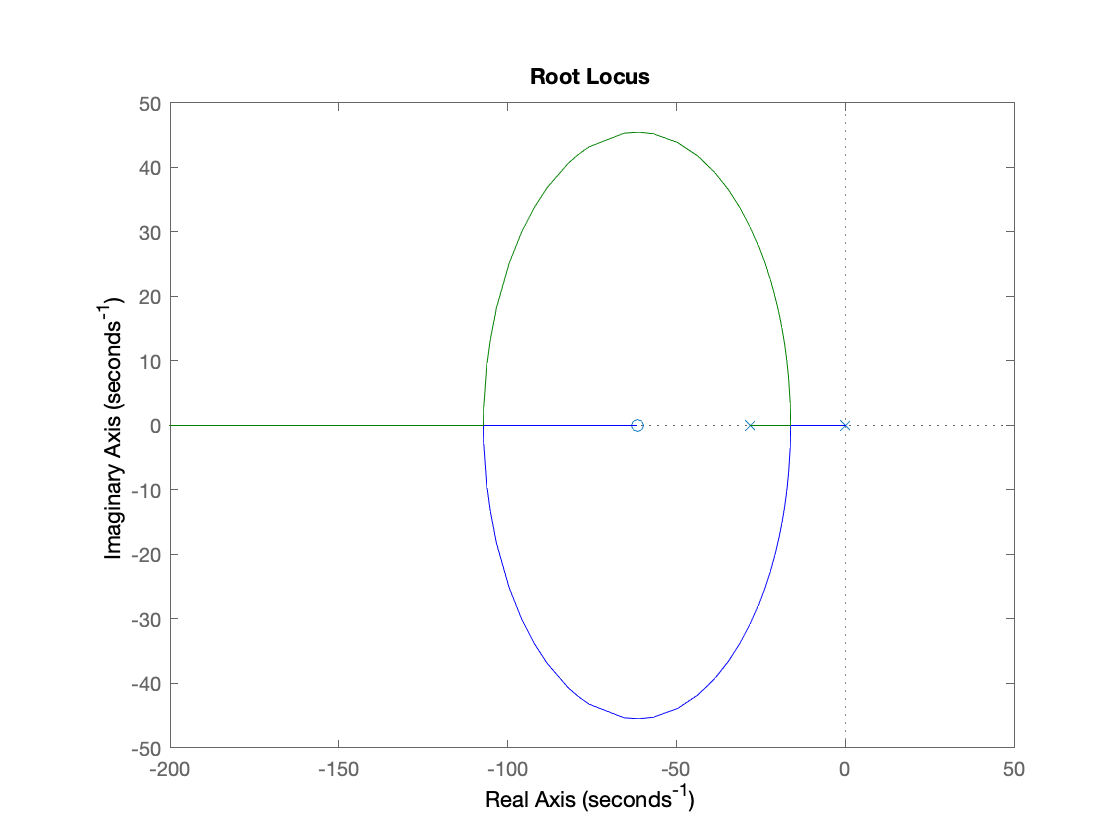

rlocus(Gma)

## Decompondo o sistema

G1 = tf(1,[1 10])

G1 =
 
    1
  ------
  s + 10
 
Continuous-time transfer function.



G2 = tf(1,[1 10])

G2 =
 
    1
  ------
  s + 10
 
Continuous-time transfer function.



G3 = tf([1 1000],1)

G3 =
 
  s + 1000
 
Continuous-time transfer function.



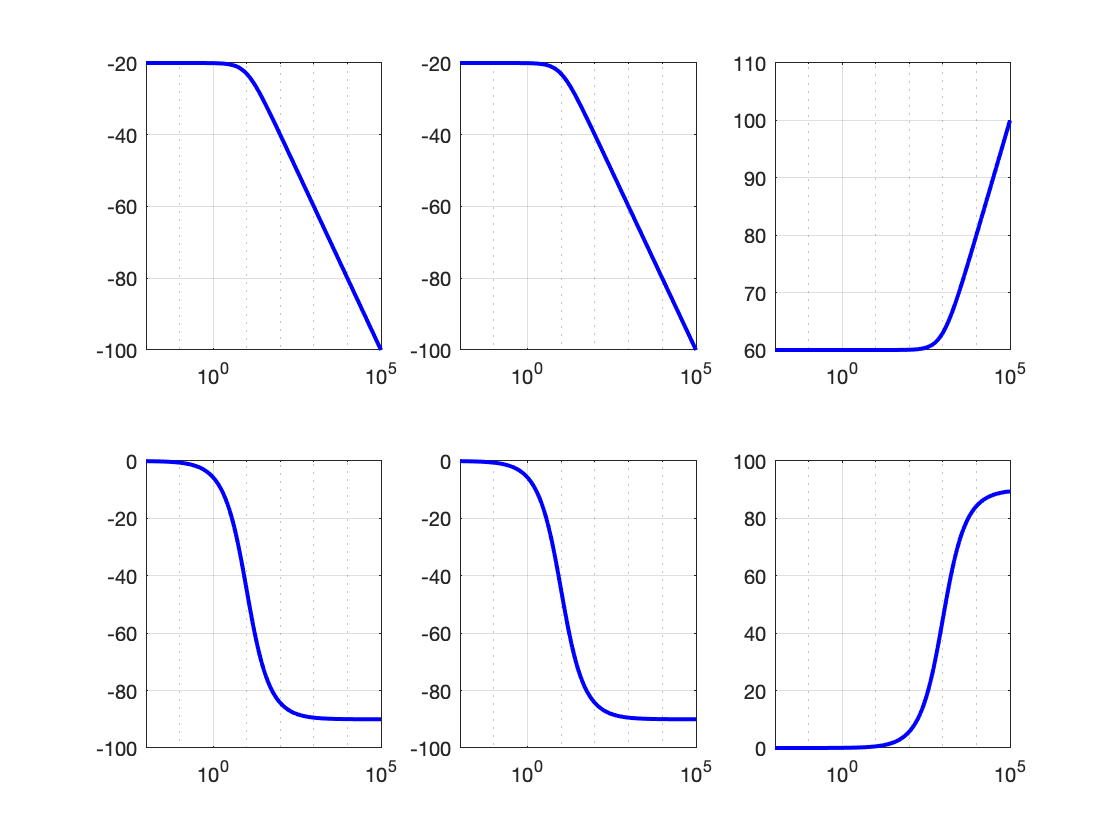

[mag1,phase1,w1] = bode(G1,{0.01,1e5});
[Gm1,Pm1,Wcg1,Wcp1] = margin(G1);

[mag2,phase2,w2] = bode(G2,{0.01,1e5});
[Gm2,Pm2,Wcg2,Wcp2] = margin(G2);

[mag3,phase3,w3] = bode(G3,{0.01,1e5});
[Gm3,Pm3,Wcg3,Wcp3] = margin(G3);


%%% Visualizando as respostas

figure(2)

subplot(2,3,1)
semilogx(w1, 20*log10(squeeze(mag1)), '-b', 'LineWidth',2);
grid;
subplot(2,3,4)
semilogx(w1, squeeze(phase1), '-b', 'LineWidth',2);
grid;

subplot(2,3,2)
semilogx(w2, 20*log10(squeeze(mag2)), '-b', 'LineWidth',2);
grid;
subplot(2,3,5)
semilogx(w2, squeeze(phase2), '-b', 'LineWidth',2);
grid;

subplot(2,3,3)
semilogx(w3, 20*log10(squeeze(mag3)), '-b', 'LineWidth',2);
grid;
subplot(2,3,6)
semilogx(w3, squeeze(phase3), '-b', 'LineWidth',2);
grid;

## Sobrepondo para um melhor entendimento


figure(3)

subplot(2,1,1)
semilogx(w, 20*log10(squeeze(mag)), '-b', 'LineWidth',2);
xline(Wcp,'r-.','LineWidth',2);
yline(0,'r-.','LineWidth',2);
grid;
hold;

Current plot held


semilogx(w1, 20*log10(squeeze(mag1)), 'g--', 'LineWidth',2);
semilogx(w2, 20*log10(squeeze(mag2)), 'y--', 'LineWidth',2);
semilogx(w3, 20*log10(squeeze(mag3)), 'k--', 'LineWidth',2);

subplot(2,1,2);
semilogx(w, squeeze(phase), '-b', 'LineWidth',2);
xline(Wcp,'r-.','LineWidth',2);
yline(-180,'r-.','LineWidth',2);
grid;
hold;

Current plot held


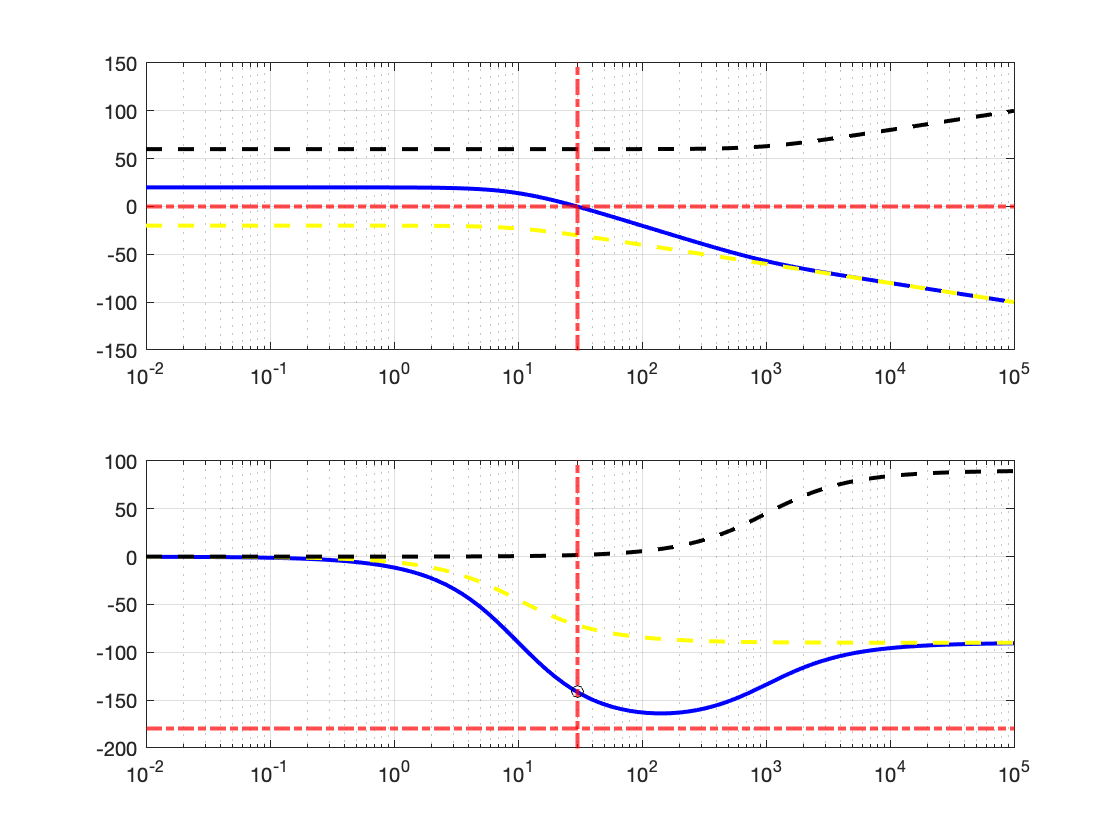

semilogx(w1, squeeze(phase1), 'g--', 'LineWidth',2);
semilogx(w2, squeeze(phase2), 'y--', 'LineWidth',2);
semilogx(w3, squeeze(phase3), 'k--', 'LineWidth',2);
plot(Wcp,-180+Pm,'ko');